cd('/Volumes/PcSSDA/RvR/20220330_1610_RvR_003')
ExperimentName='20220330_1610_RvR_003'; % Give a specific name to this experiment or this analysis
FirstAcq=7;
number_of_acq = 1;

analysis_name=[ExperimentName,'_analysis_'];
timebin=1;
ch=1;
FLPfiles='continuous aquistion data_'; 

i=1;
filename=[analysis_name,num2str(i),'_20220403.mat'];
load(filename)

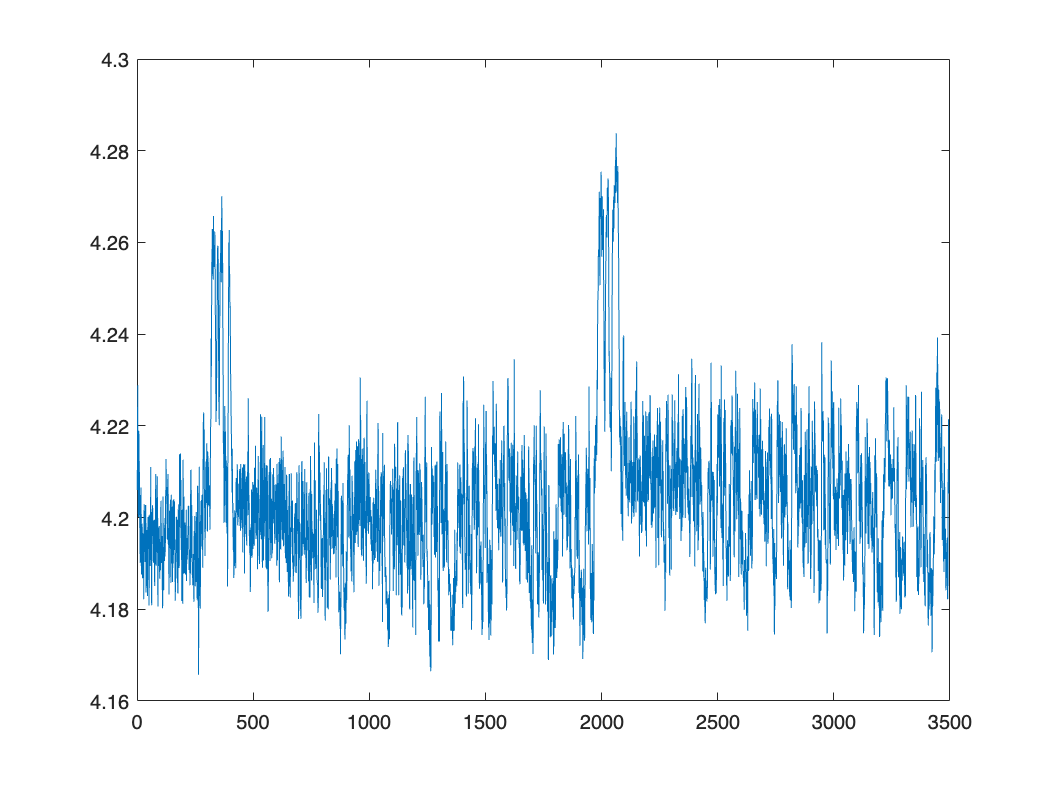

figure
plot(tau_empTrunc)

resting_index = 149;
running_index = 331;
resting_histogram = lifetime_histograms(:,resting_index);
running_histogram = lifetime_histograms(:,running_index);
resting_histogram_norm = resting_histogram/max(resting_histogram);
running_histogram_norm = running_histogram/max(running_histogram);

cd('/Volumes/PcSSDA/1610/20220328_1610_SW_005')
ExperimentName='20220328_1610_SW_005'; % Give a specific name to this experiment or this analysis
FirstAcq=10; % What's the acquisition number of the first offical recording
number_of_acq = 17; % How many chunks of recordings are there?
Dark_hours=[10 11 12 13 14 15 16 17 18 19 20 21 22]

Dark_hours =     10    11    12    13    14    15    16    17    18    19    20    21    22


darktime_calc = 0; % 0 or 1, determining different method to calculate dark time
post_savedfiles='20220426';

analysis_name=[ExperimentName,'_analysis_'];
timebin=1;
ch=1;
FLPfiles='continuous aquistion data_'; 

load('FLP_analysis_0426.mat')

i = 2;
filename=[analysis_name,num2str(i),'h_',post_savedfiles,'.mat'];
load(filename)

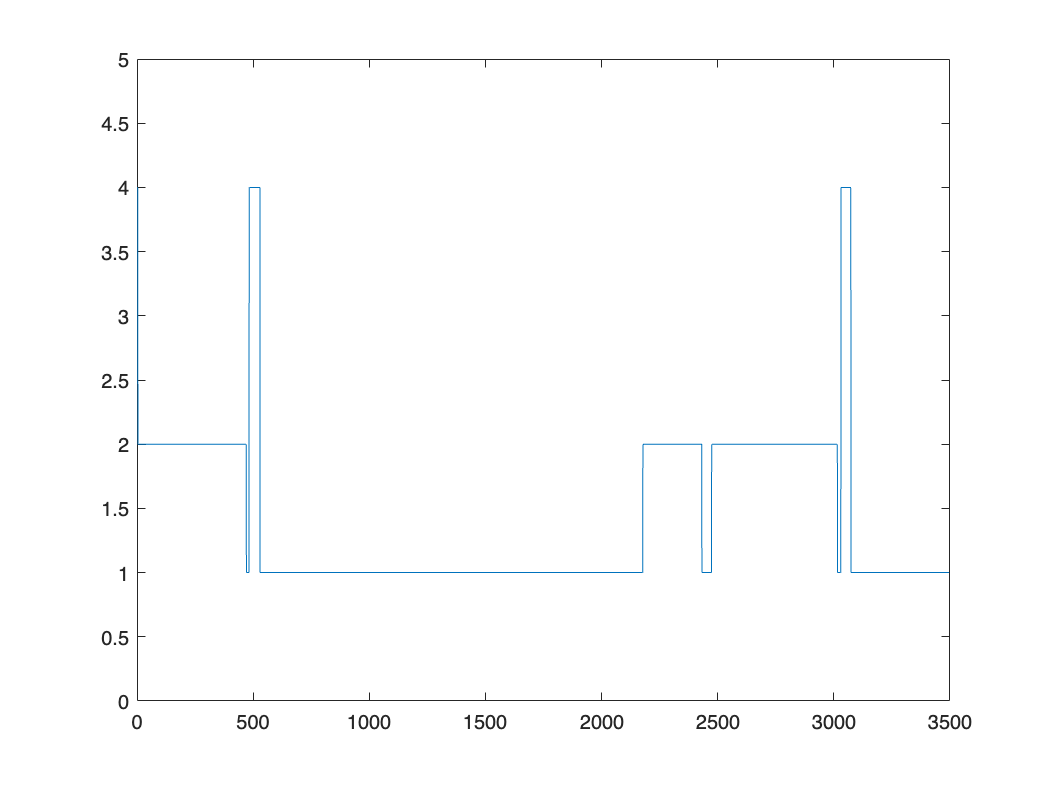

figure
plot(states_for_time_11)
ylim([0 5])

NREM_index = 252;
AW_index = 732;
NREM_histogram = lifetime_histograms(:,NREM_index);
AW_histogram = lifetime_histograms(:,AW_index);
NREM_histogram_norm = NREM_histogram/max(NREM_histogram);
AW_histogram_norm = AW_histogram/max(AW_histogram);

nsPerPoint = 25/256;
lft_points=[1:1:169]*nsPerPoint;
lft_all = zeros(1, 4);
histogram_names = {'resting_histogram','running_histogram','NREM_histogram','AW_histogram'};
for i = 1:4
    eval(['empirical_lifetimes = ', histogram_names{i}, '(22:190);'])
    lft_all(i)=sum(empirical_lifetimes.*lft_points')/sum(empirical_lifetimes);

end

lft_all

lft_all =     4.1912    4.2538    4.1295    4.1932


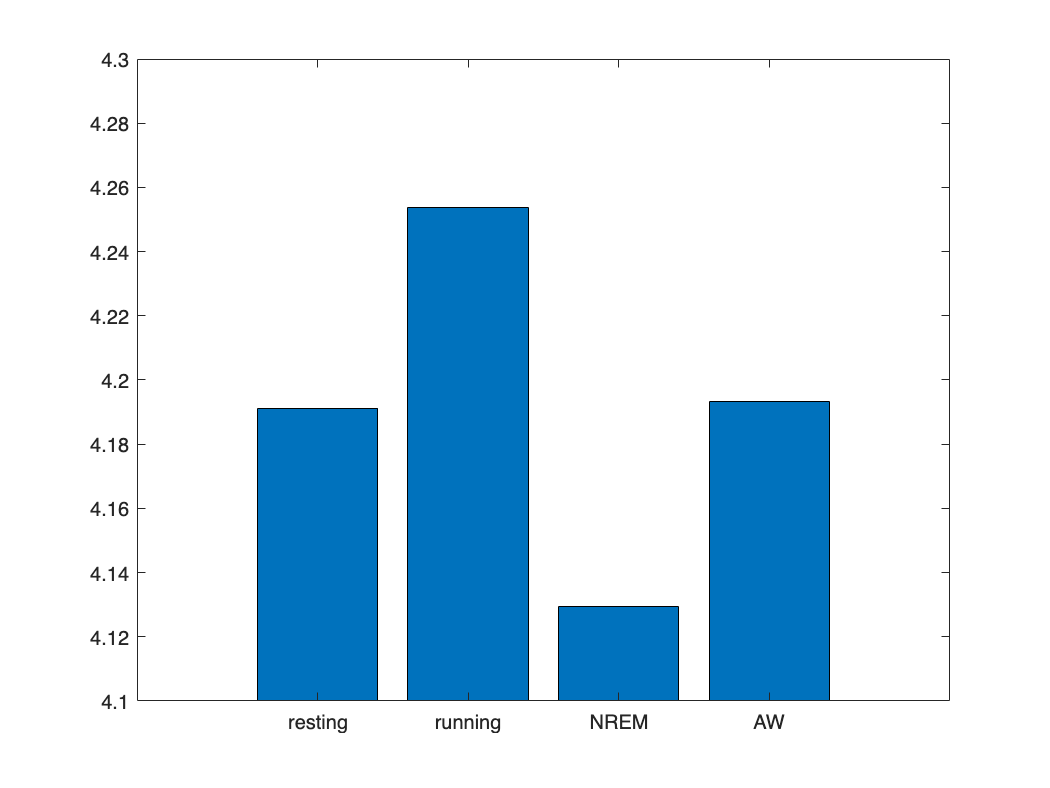

figure
bar(lft_all)
ylim([4.1, 4.3])
set(gca, 'XTickLabel', {'resting', 'running', 'NREM', 'AW'})

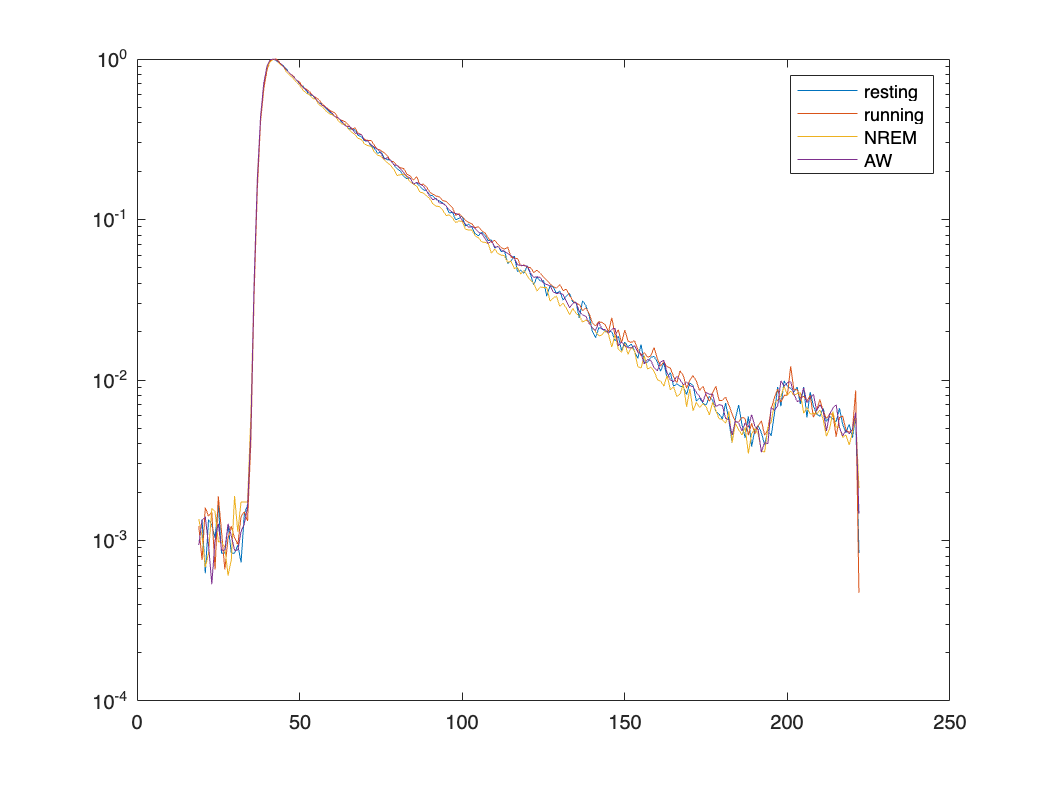

figure
semilogy(resting_histogram_norm)
hold on
semilogy(running_histogram_norm)
hold on
semilogy(NREM_histogram_norm)
hold on
semilogy(AW_histogram_norm)
legend('resting', 'running', 'NREM', 'AW')

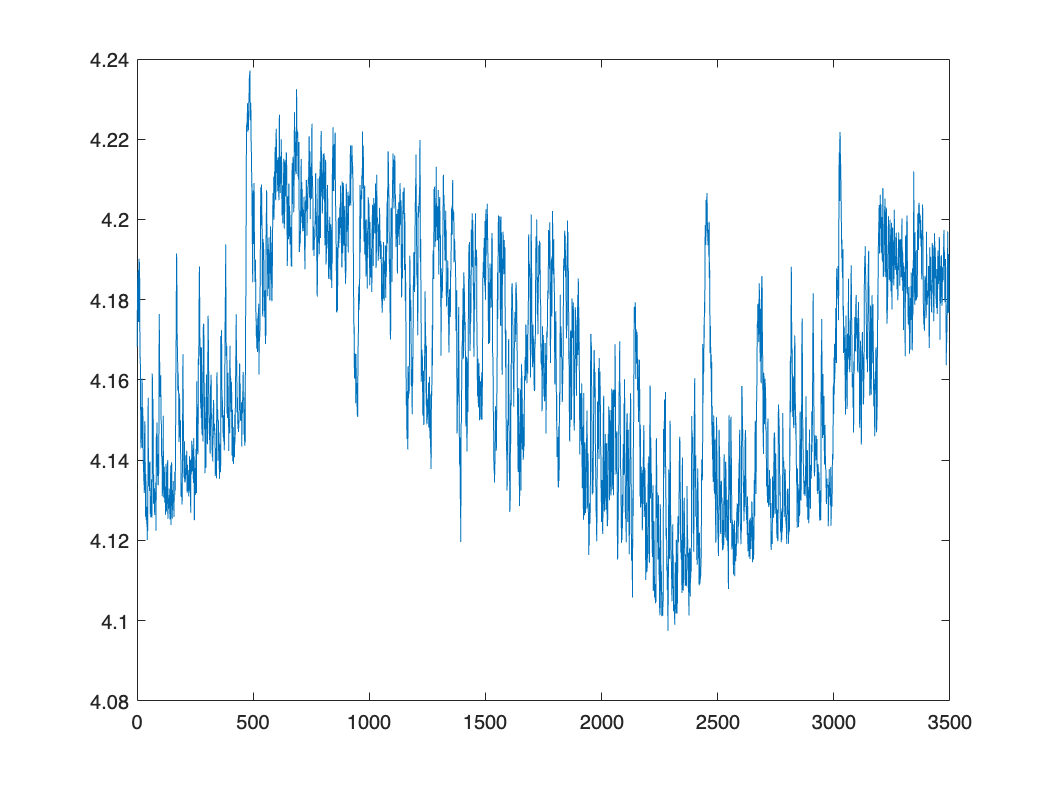

figure
plot(tau_empTrunc)